
% Pacheck, Nicholas
% 1-D Beamforming Patterns
clc, clear, clearvars
% Define signal parameters
freq = 10e6;
omega = 2*pi*freq;
speed0light = 3e8;
wavelen = speed0light/freq;

% Define array parameters
spacing = wavelen/2;
nAntennas = 5;
array_length = spacing*nAntennas;

% Define Antenna Element coordinates
x_coords = linspace(0, array_length, nAntennas);

% Define azimuthal vector span
azimSpan = linspace(-90, 90, 180);

% Define Element Factor
EF = 1;
%Define AOA
AOA = -16

AOA = -16


% Define Element Pattern
EP = (cosd(azimSpan)).^(EF/2); % reduces side lobe grating

% Define Array factor
AF = 0

AF = 0

for i = 1:nAntennas

    % Compute phase shift
    phase_shift = (2*pi/wavelen)*x_coords(i)*(sind(azimSpan) - sind(AOA));

    % Compute steering weight
    steer = exp(j*phase_shift);

    % SUM
    AF = (AF + steer);

end

AF = AF/nAntennas

AF =    0.1235 + 0.0834i   0.1232 + 0.0834i   0.1224 + 0.0835i   0.1211 + 0.0837i   0.1192 + 0.0839i   0.1167 + 0.0841i   0.1138 + 0.0843i   0.1102 + 0.0844i   0.1061 + 0.0843i   0.1014 + 0.0840i   0.0962 + 0.0835i   0.0904 + 0.0826i   0.0841 + 0.0812i   0.0774 + 0.0793i   0.0701 + 0.0767i   0.0625 + 0.0733i   0.0546 + 0.0691i   0.0466 + 0.0639i   0.0384 + 0.0576i   0.0303 + 0.0502i   0.0225 + 0.0415i   0.0152 + 0.0315i   0.0085 + 0.0203i   0.0028 + 0.0077i  -0.0018 - 0.0060i  -0.0050 - 0.0209i  -0.0064 - 0.0368i  -0.0060 - 0.0534i  -0.0033 - 0.0705i   0.0016 - 0.0877i   0.0091 - 0.1046i   0.0192 - 0.1209i   0.0318 - 0.1360i   0.0469 - 0.1493i   0.0642 - 0.1605i   0.0834 - 0.1688i   0.1041 - 0.1739i   0.1257 - 0.1754i   0.1474 - 0.1728i   0.1685 - 0.1661i   0.1879 - 0.1552i   0.2049 - 0.1403i   0.2184 - 0.1217i   0.2274 - 0.1002i   0.2311 - 0.0765i   0.2288 - 0.0518i   0.2200 - 0.0274i   0.2045 - 0.0048i   0.1825 + 0.0144i   0.1544 + 0.0284i



inte = sum(abs(AF))

inte = 42.1727

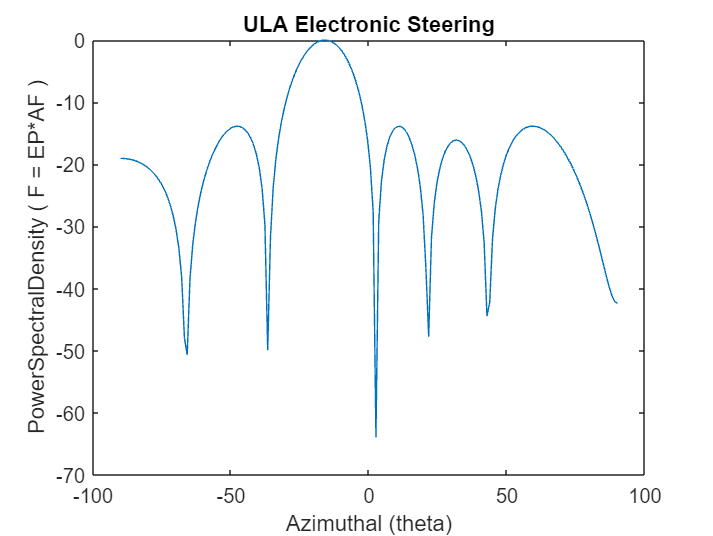


plot(azimSpan, 10*log(abs(AF)))
title("ULA Electronic Steering")
xlabel("Azimuthal (theta)")
ylabel("PowerSpectralDensity ( F = EP*AF )")